# Proyecto de grado

## Corte en trapecio y V por cinematica directa

clear all
close all

Se generan las alturas aleatorias;

yo1 = randi(30)*10;
yo2 = randi(30)*10;
yo3 = randi(30)*10;
yo4 = randi(30)*10;
yo5 = randi(30)*10;

Se fija el limite de altura:

yt = 300;

Se fija el ancho del trapecio (si es 0 hace un corte en "v")

yv = 30;

Calcula punto por punto las funciones de los corte y se selecciona el minimo de esta generando el patron:

yf = zeros(1,1501);
for x = 0:1500
    y1 = max(abs(x-250),yv)-yv + yo1;
    y2 = max(abs(x-500),yv)-yv + yo2;
    y3 = max(abs(x-750),yv)-yv + yo3;
    y4 = max(abs(x-1000),yv)-yv + yo4;
    y5 = max(abs(x-1250),yv)-yv + yo5;
    y6 = abs(x-1500); 
    yf(x+1) = min([y1 y2 y3 y4 y5 y6 yt]); 
end

Se grafica el resultado

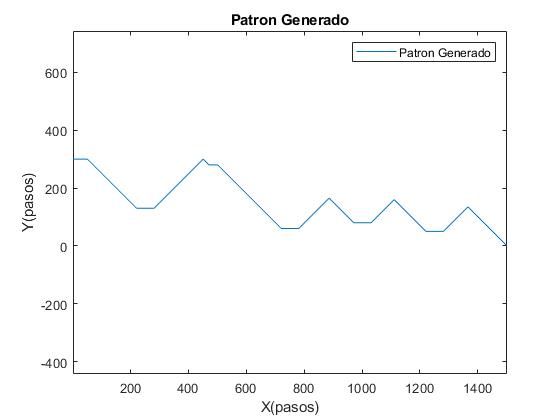

plot(yf)
axis("equal")
legend("Patron Generado")
title("Patron Generado")
xlabel("X(pasos)")
ylabel("Y(pasos)")

## Corte en trapecio y V por cinematica inversa

clear all
close all

Se generan las alturas aleatorias;

yo1 = randi(10)*0;
yo2 = randi(10)*0;
yo3 = randi(10)*0;
yo4 = randi(10)*0;
yo5 = randi(10)*0;

Se fija el limite de altura:

yt = 4;

Se fija el ancho del trapecio (si es 0 hace un corte en "v")

yv = 0.5;

Calcula punto por punto las funciones de los corte y se selecciona el minimo de esta generando el patron:

xk = 0:0.1:27;
yk = zeros(1,271);
%en cm
for i = 0:270
    y1 = max(abs(xk(i+1)-6),yv)-yv + yo1;
    y2 = max(abs(xk(i+1)-9.8),yv)-yv + yo2;
    y3 = max(abs(xk(i+1)-13.6),yv)-yv + yo3;
    y4 = max(abs(xk(i+1)-17.4),yv)-yv + yo4;
    y5 = max(abs(xk(i+1)-21.2),yv)-yv + yo5;
    y6 = abs(xk(i+1)-27); 
    yk(i+1) = min([y1 y2 y3 y4 y5 y6 yt]); 
end

%llave 1000 0.56 0.96 1.36 1.76 2.16 2.7 

Se grafica el resultado

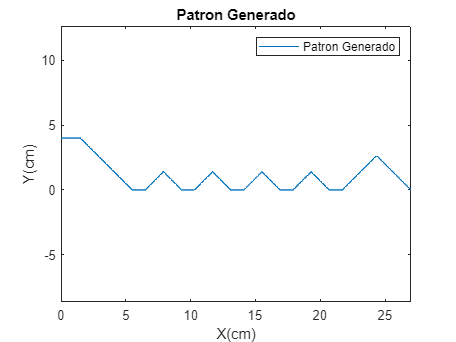

plot(xk,yk)
axis("equal")
legend("Patron Generado")
title("Patron Generado")
xlabel("X(cm)")
ylabel("Y(cm)")

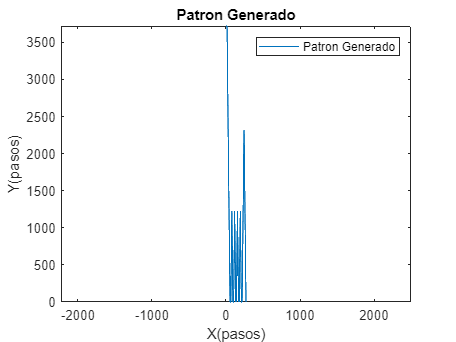


theta = acosd((0.4-yk)/6);
yp = round(theta*32/0.35);
ypf = yp-min(yp);

plot(ypf)
axis("equal")
legend("Patron Generado")
title("Patron Generado")
xlabel("X(pasos)")
ylabel("Y(pasos)")

## Simulacion

Modelo DH

%%clear all
%%close all
syms l theta
L = 6;
L01 = Link('theta',pi/2,'a',0,'alpha',pi/2)

 
L01 = 
Prismatic(std): theta=1.5708, d=q, a=0, alpha=1.5708, offset=0


L02 = Link('theta',pi/2,'a',0,'alpha',0)

 
L02 = 
Prismatic(std): theta=1.5708, d=q, a=0, alpha=0, offset=0


L1 = Link('theta',0,'a',0,'alpha',0)

 
L1 = 
Prismatic(std): theta=0, d=q, a=0, alpha=0, offset=0


L2 = Link('d',0,'a',6.5,'alpha',0,'offset',-pi/2+70*pi/180)

 
L2 = 
Revolute(std): theta=q, d=0, a=6.5, alpha=0, offset=-0.349066


bot = SerialLink([L01 L02 L1,L2],'name','Maquina')

 
bot = 
 
Maquina:: 4 axis, PPPR, stdDH, slowRNE                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|     1.5708|         q1|          0|     1.5708|          0|
|  2|     1.5708|         q2|          0|          0|          0|
|  3|          0|         q3|          0|          0|          0|
|  4|         q4|          0|        6.5|          0|  -0.349066|
+---+-----------+-----------+-----------+-----------+-----------+
 


Pd = [0 0 10 4*pi/180];
W=[0,15,-10,10,-5,10];
bot.plot(Pd,'workspace',W)

Af1= bot.fkine([0 0 10 0]);
pf1 = Af1.t

pf1 =    10.0000
    2.2231
    6.1080


Af2= bot.fkine(Pd);
pf2 = Af2.t

pf2 =    10.0000
    1.7916
    6.2482


diff = pf1(2)-pf2(2)

diff = 0.4315

ycut = 6;
d = 0;
x = 5;
d = 0.5;
y = ycut-d;
theta = acos(y/L);
thetag = acosd(y/L)

thetag = 23.5565


pd = [0 0 x theta] ;
W=[0,4,0,7,-5,6];

xKEY = 0:1500;
yKEY = ypf; 

xk = xKEY*(2.7/1500);
thetak = -yKEY*((0.35/32)*pi/180);
C = zeros(1,3)

C =      0     0     0



for i = 1:length(xk)
    A = bot.fkine([0 0 xk(i) thetak(i)]);
    Xp = A.t(1);
    Yp = A.t(2);
    C(i,:) = [Xp Yp 0];
    
%     if mod(i,10)==0
%             clf
%             figure(1)
%             bot.plot([0 0 xk(i) thetak(i)],'workspace',W)
%             view(-90,0)
%     end

    %figure(2)
    %plot(C(:,1),C(:,2))
    
end
C(:,2) = C(:,2) - min(C(:,2))

C =    -0.0000    0.4028         0
    0.0018    0.4028         0
    0.0036    0.4028         0
    0.0054    0.4028         0
    0.0072    0.4028         0
    0.0090    0.4028         0
    0.0108    0.4028         0
    0.0126    0.4028         0
    0.0144    0.4028         0
    0.0162    0.4028         0


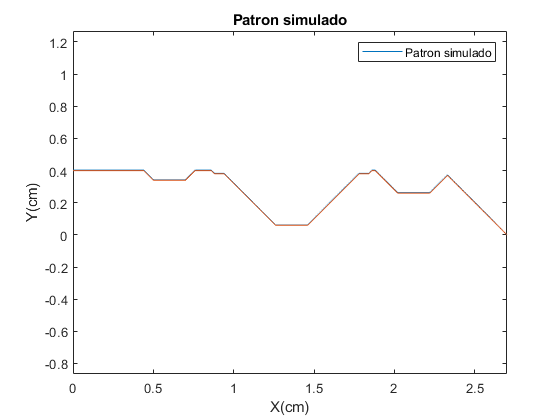


close all
plot(C(:,1),C(:,2),xk,yk)
axis("equal")
title("Patron simulado")
legend("Patron simulado")
xlabel("X(cm)")
ylabel("Y(cm)")

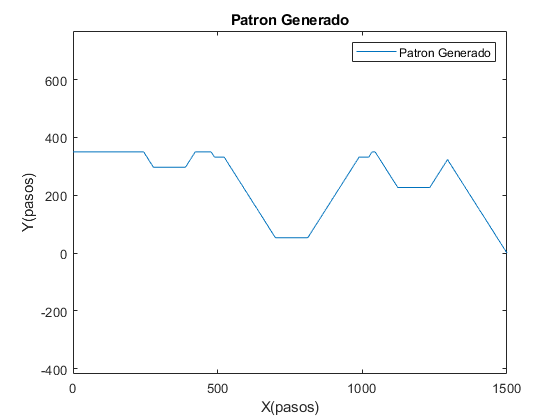

clf
plot(xKEY,yKEY)
axis("equal")
legend("Patron Generado")
title("Patron Generado")
xlabel("X(pasos)")
ylabel("Y(pasos)")

max(C(:,2))-min(C(:,2))

ans = 0.4028